# Parte 2

## Generar el archivo codificado con PCM 64 con ley A

Leo el audio 

[https://www.mathworks.com/help/matlab/ref/audioread.html](https://www.mathworks.com/help/matlab/ref/audioread.html)

[y_, Fs_] = audioread('recording.mp3');
Fs_

Fs_ = 44100

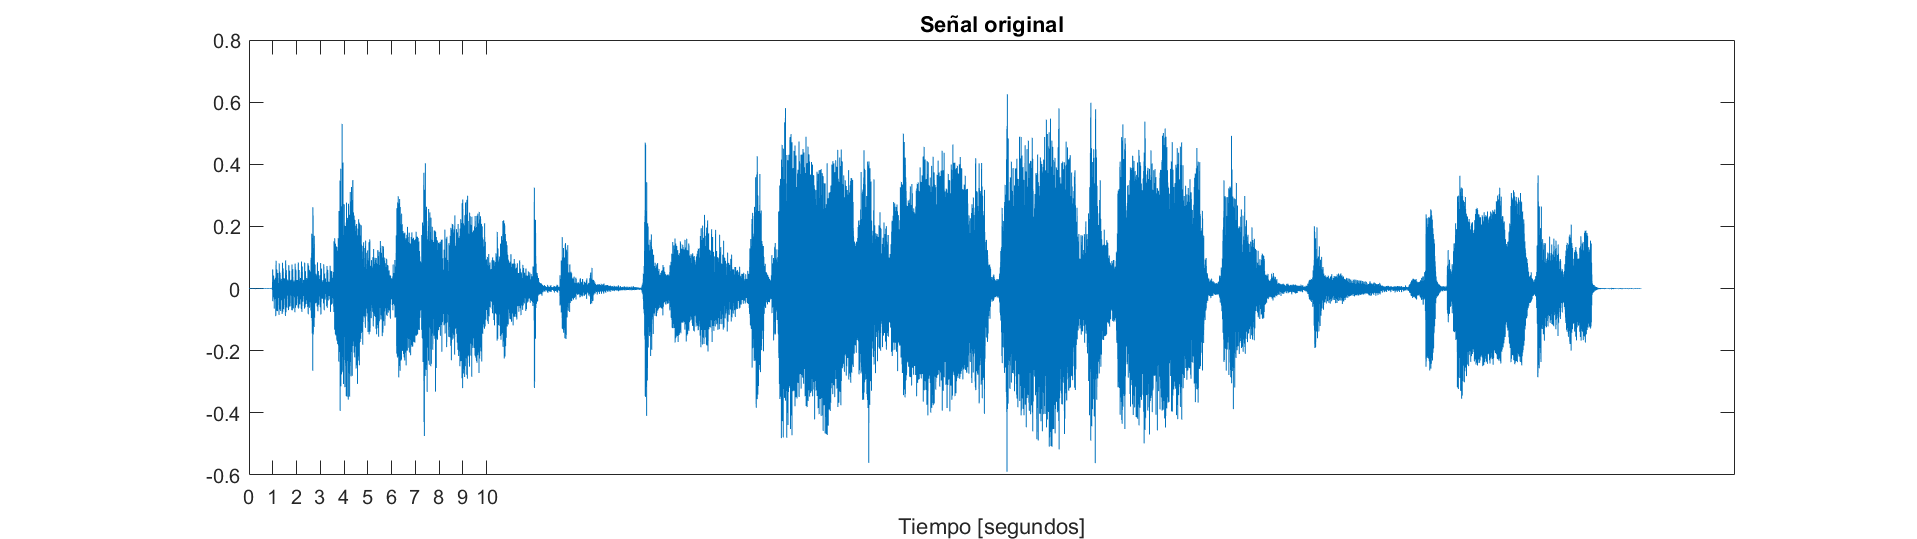

h = figure();
plot(y_)
xlabel("Tiempo [segundos]")
xticks([0:8000:8000*10])
xticklabels(["0","1","2","3","4","5","6","7","8","9","10"])
title("Señal original")
set(h,'Units','normalized','Position',[0 0 1 .5]); 

Downsapling a 8kHz

[https://www.mathworks.com/help/signal/ug/changing-signal-sample-rate.html](https://www.mathworks.com/help/signal/ug/changing-signal-sample-rate.html)

Fs = 8000

Fs = 8000

[P, Q] = rat(Fs/Fs_);
y = resample(y_, P, Q);

Aplicamos Ley A:

[https://es.wikipedia.org/wiki/Ley_A](https://es.wikipedia.org/wiki/Ley_A)

[https://www.mathworks.com/help/comm/ref/compand.html](https://www.mathworks.com/help/comm/ref/compand.html)

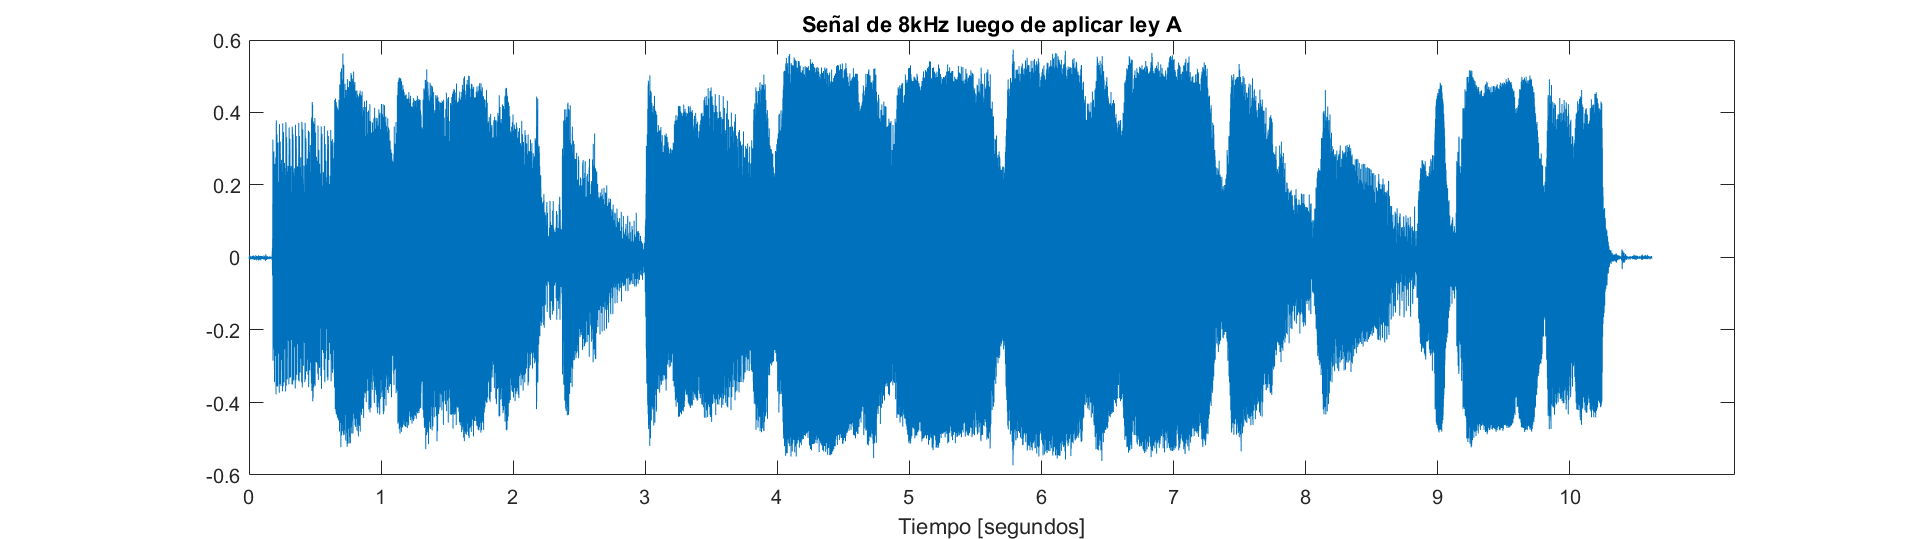

compressed = compand(y,87.6,max(y),'A/compressor');
plot(compressed)
xlabel("Tiempo [segundos]")
xticks([0:8000:8000*10])
xticklabels(["0","1","2","3","4","5","6","7","8","9","10"])
title("Señal de 8kHz luego de aplicar ley A")

Cuantizamos la señal

[https://www.mathworks.com/help/comm/ref/quantiz.html](https://www.mathworks.com/help/comm/ref/quantiz.html)

levels = 64

levels = 64

q = max(y)/(levels/2)

q = 0.0179

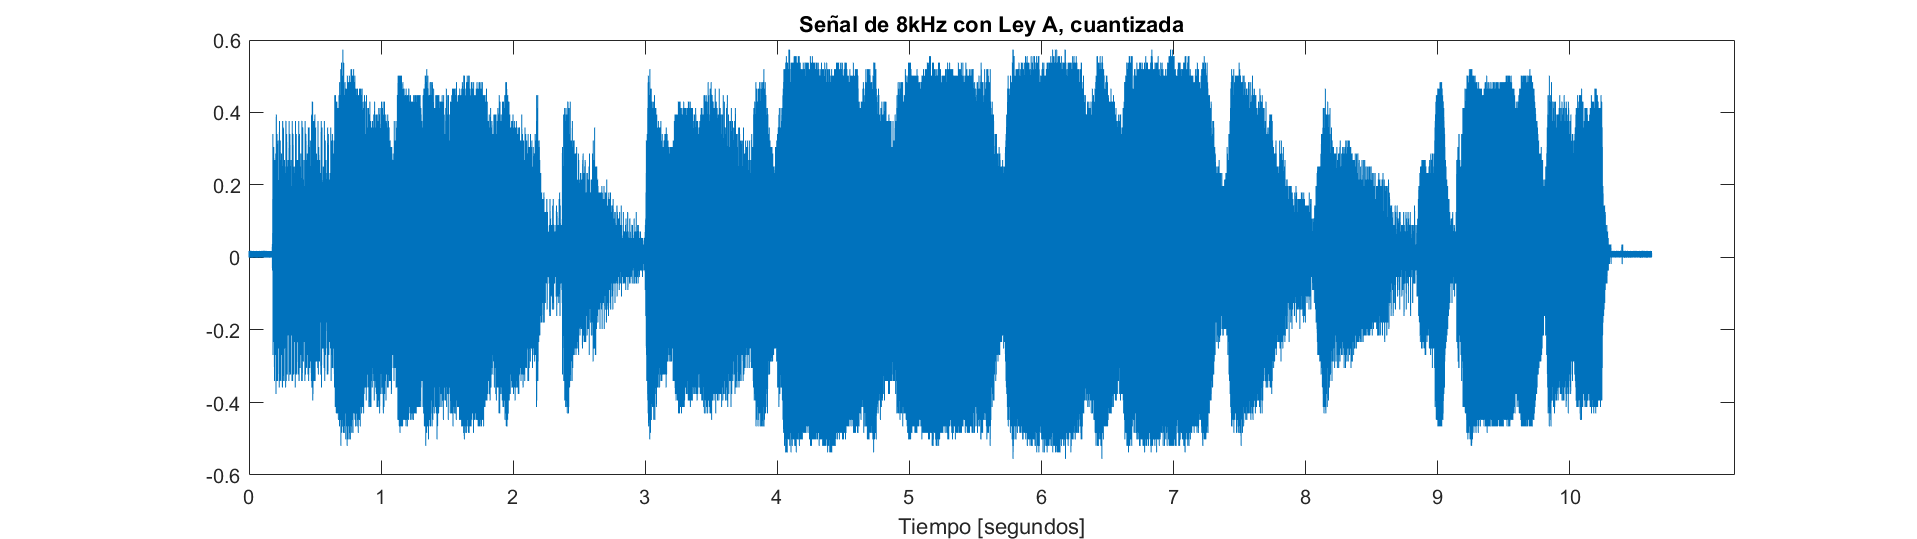

partition = -max(y):q:max(y)-q;
codebook = -max(y):q:max(y);
[index, quants, distor] = quantiz(compressed, partition, codebook);

plot(quants)
xlabel("Tiempo [segundos]")
xticks([0:8000:8000*10])
xticklabels(["0","1","2","3","4","5","6","7","8","9","10"])
title("Señal de 8kHz con Ley A, cuantizada")

Recupero la señal

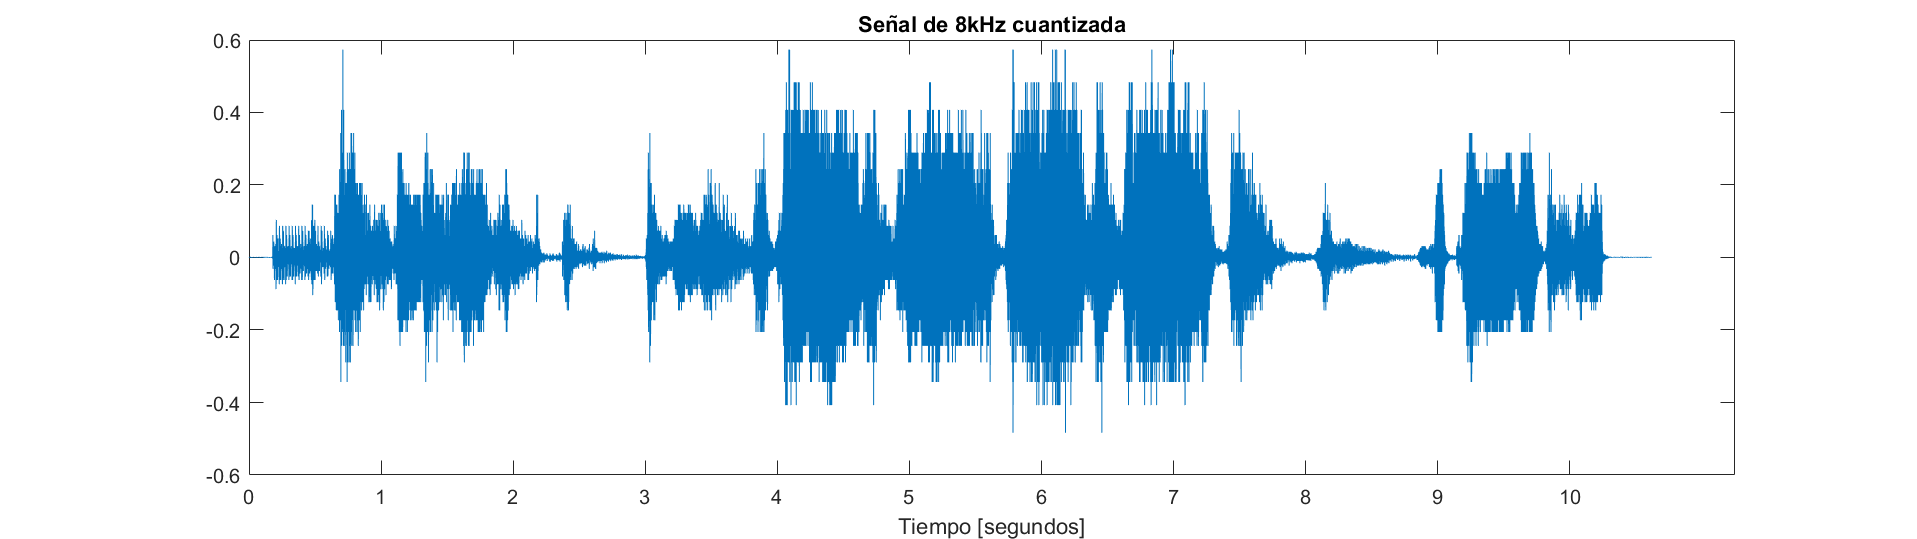

expanded = compand(quants, 87.6, max(y), 'A/expander');
plot(expanded)
xlabel("Tiempo [segundos]")
xticks([0:8000:8000*10])
xticklabels(["0","1","2","3","4","5","6","7","8","9","10"])
title("Señal de 8kHz cuantizada")

Guardo el audio

samples = Fs*20e-3;
% guardo un múltiplo de samples
len = floor(length(expanded)/samples) * samples; 
audiowrite('audioPCM64.wav', expanded(1:len), Fs)

## Agregar ruido

Se lee la señal previamente generada

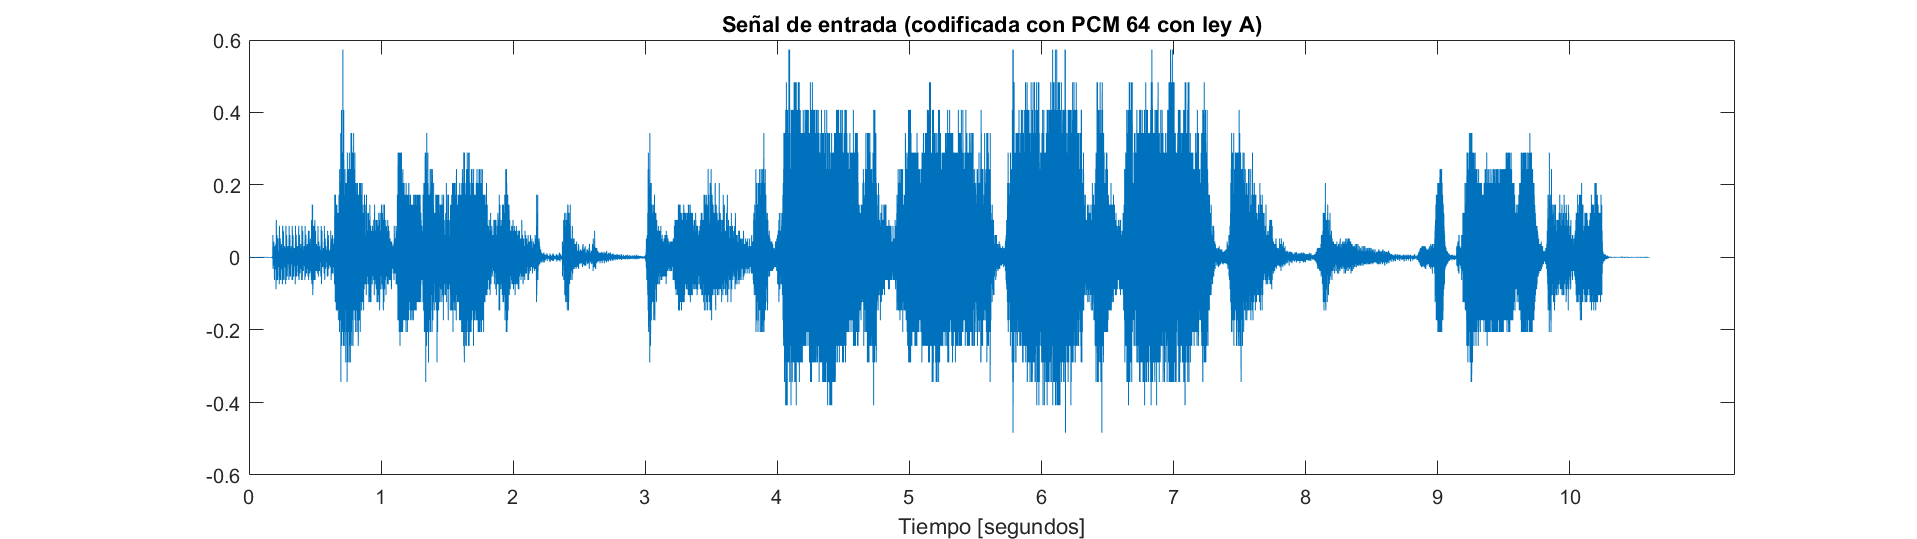

[signal, Fs] = audioread('audioPCM64.wav');
plot(signal)
xlabel("Tiempo [segundos]")
xticks([0:8000:8000*10])
xticklabels(["0","1","2","3","4","5","6","7","8","9","10"])
title("Señal de entrada (codificada con PCM 64 con ley A)")

Generamos ruido blanco con varianza $\sigma^2$

[https://www.mathworks.com/help/comm/ref/wgn.html](https://www.mathworks.com/help/comm/ref/wgn.html)

varianza = 1e-3;
power_dBW = 10*log10(varianza)

power_dBW = -30

nsamples = length(signal);
wgn_samples = wgn(nsamples, 1, power_dBW);

Lo agregamos a la señal de audio

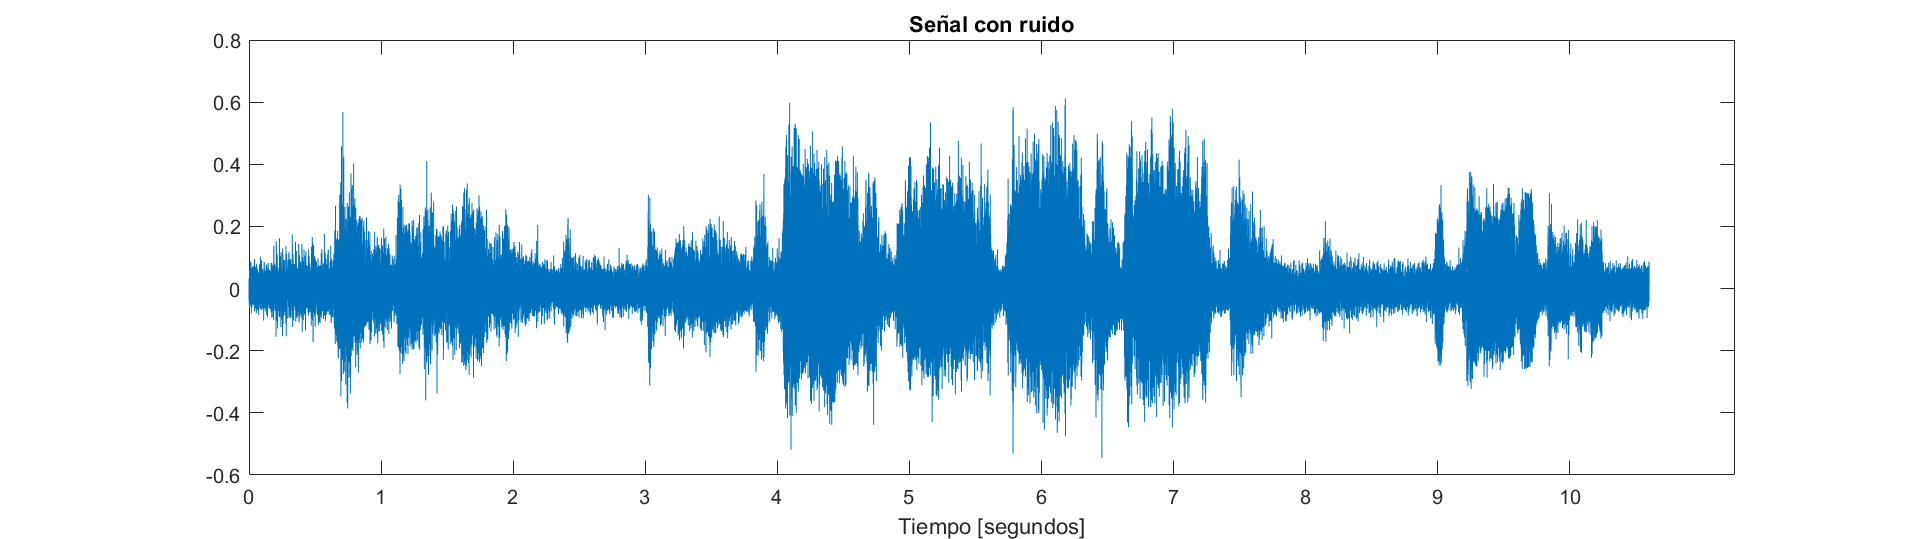

signal_with_wgn = signal + wgn_samples;
plot(signal_with_wgn)
xlabel("Tiempo [segundos]")
xticks([0:8000:8000*10])
xticklabels(["0","1","2","3","4","5","6","7","8","9","10"])
title("Señal con ruido")

audiowrite('audioPCM64_con_ruido.wav', signal_with_wgn, Fs)

## Predictor lineal óptimo

[https://www.mathworks.com/help/econ/autocorr.html](https://www.mathworks.com/help/econ/autocorr.html)

orders = 10:15;
gps = [];
signal_ests = [];

for order=orders
    signal_est = run_linear_predictor(signal_with_wgn, samples, order);
    % Ganancia de predicción
    error = signal - signal_est;
    gp = signal'*signal / (error'*error);
    gps = [gps gp];
    signal_ests = [signal_ests, signal_est];
end

Plot ganancia de predicción vs orden

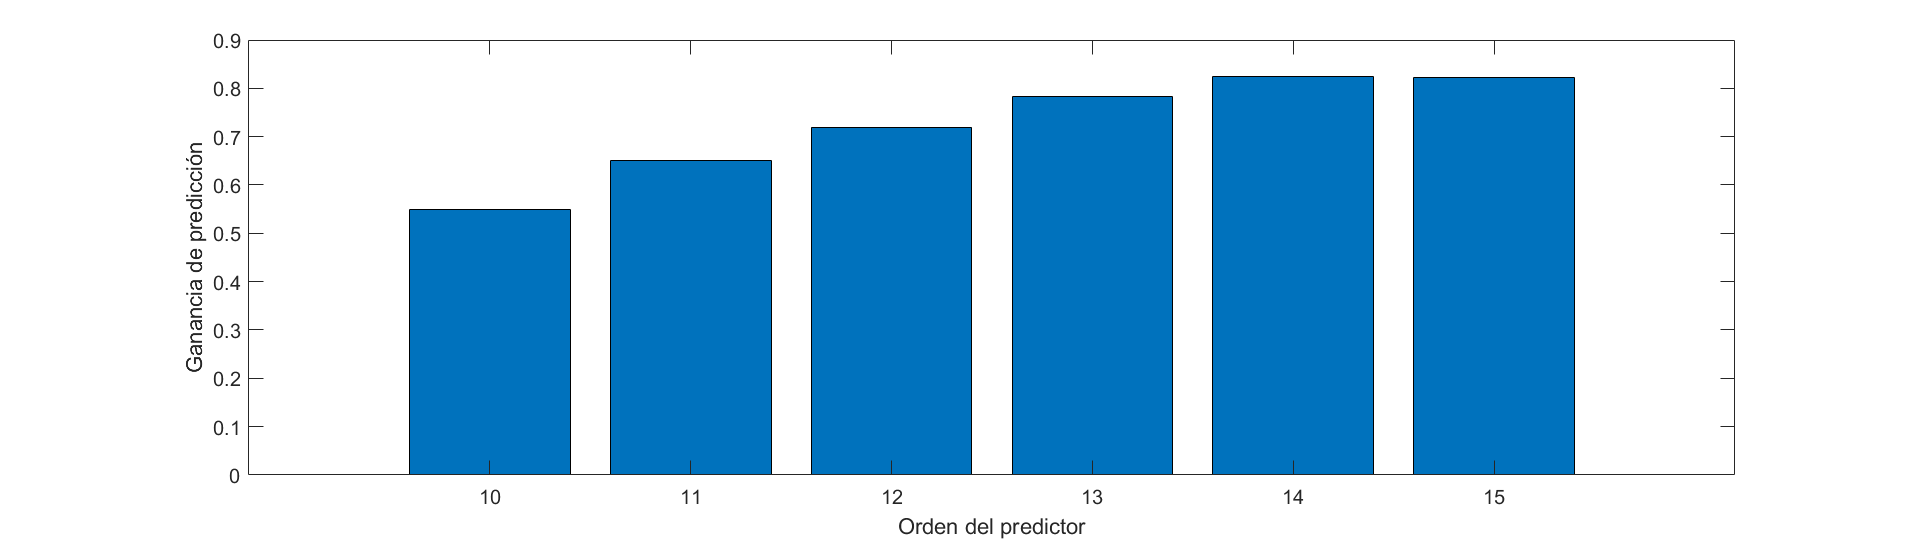

bar(orders, gps);
xlabel("Orden del predictor");
ylabel("Ganancia de predicción");

Plot de la estimación con orden 14

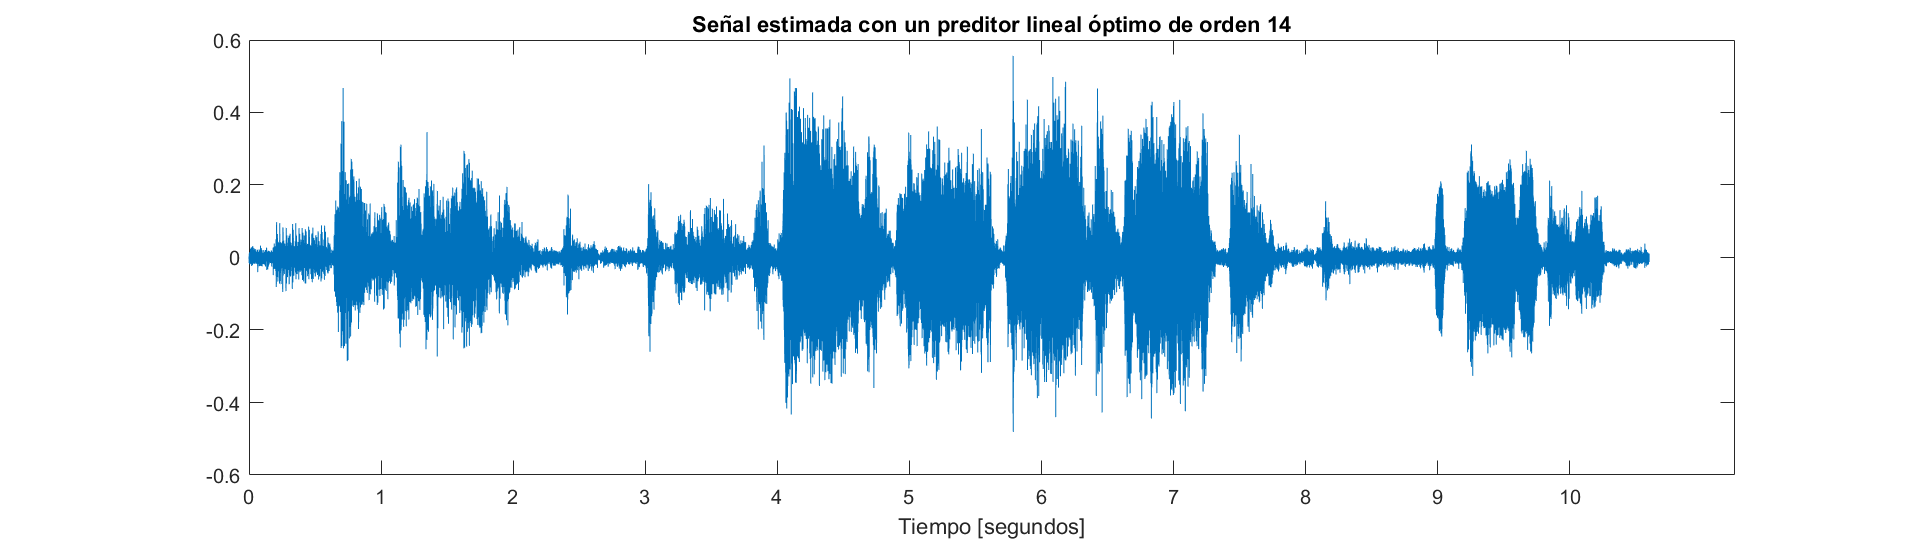

plot(signal_ests(:,5))
xlabel("Tiempo [segundos]")
xticks([0:8000:8000*10])
xticklabels(["0","1","2","3","4","5","6","7","8","9","10"])
title("Señal estimada con un preditor lineal óptimo de orden 14")

%sound(signal_ests(:,14), Fs)

%sound(signal, Fs)

%sound(signal_with_wgn, Fs)